Problem 1a

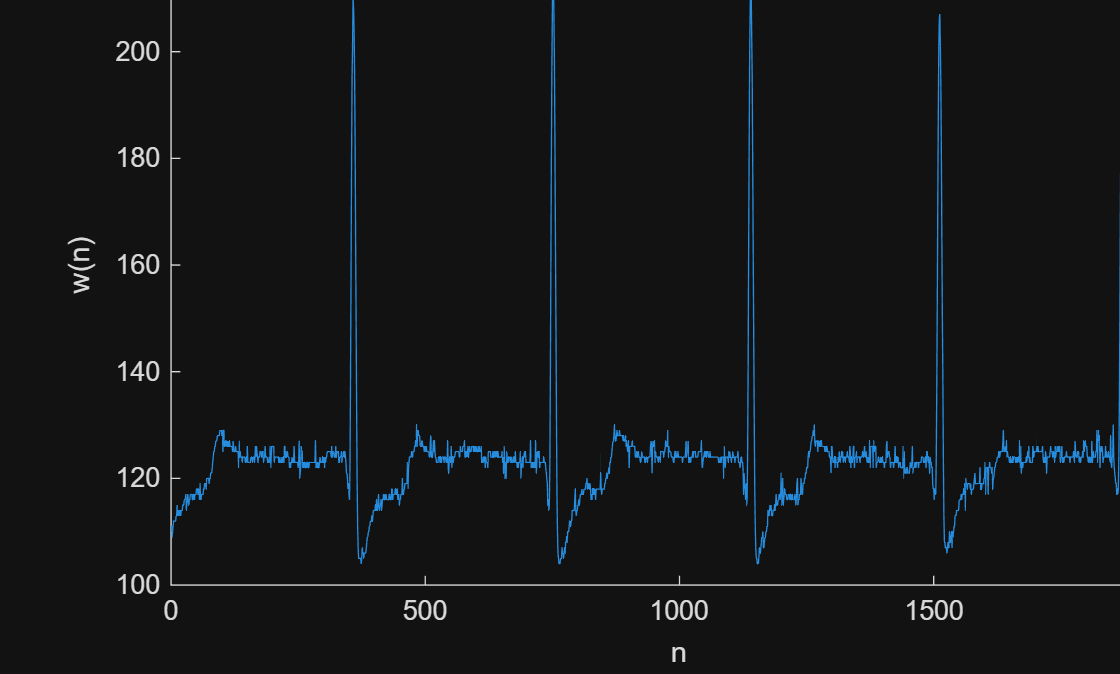

load('SAMPLE_ECG.mat')
w = ECG_Data;
n = 0:length(w)-1;

plot(n, w)
axis([0 2000 100 220]);
title('Problem 1a Ufiltered Signal');
xlabel('n');
ylabel('w(n)');

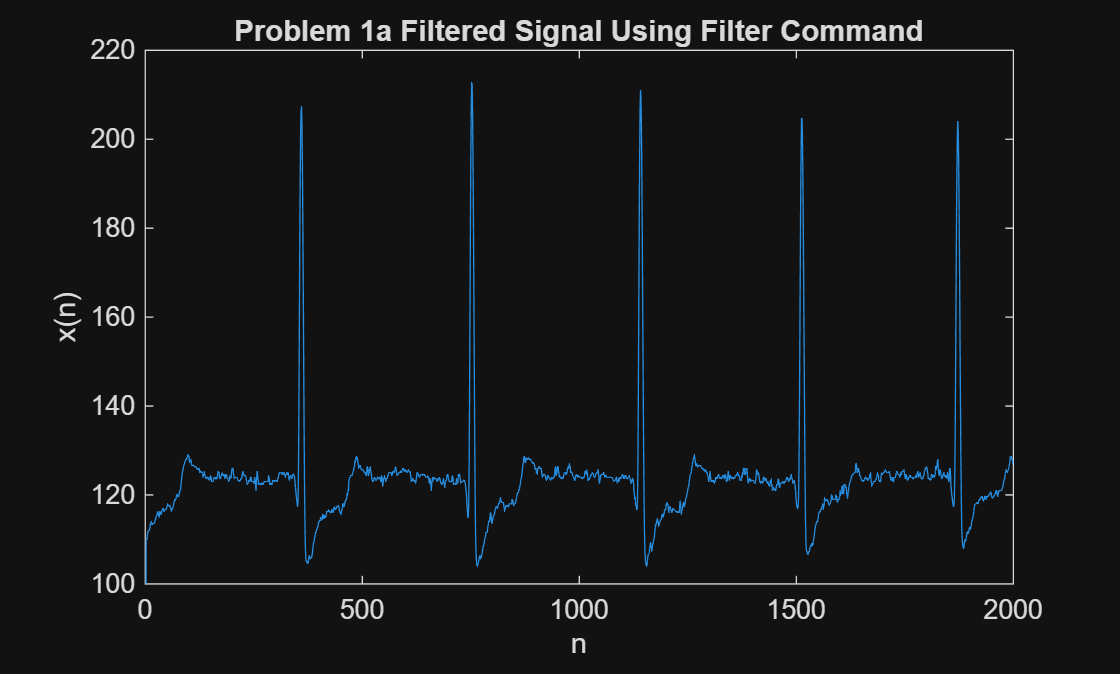


% filter command
windowSize = 3;
b = (1/windowSize)*ones(1, windowSize);
a = 1;
n = 0:length(w)-1;

x = filter(b, a, w);

plot(n, x)
axis([0 2000 100 220]);
title('Problem 1a Filtered Signal Using Filter Command');
xlabel('n');
ylabel('x(n)');

Problem 1b

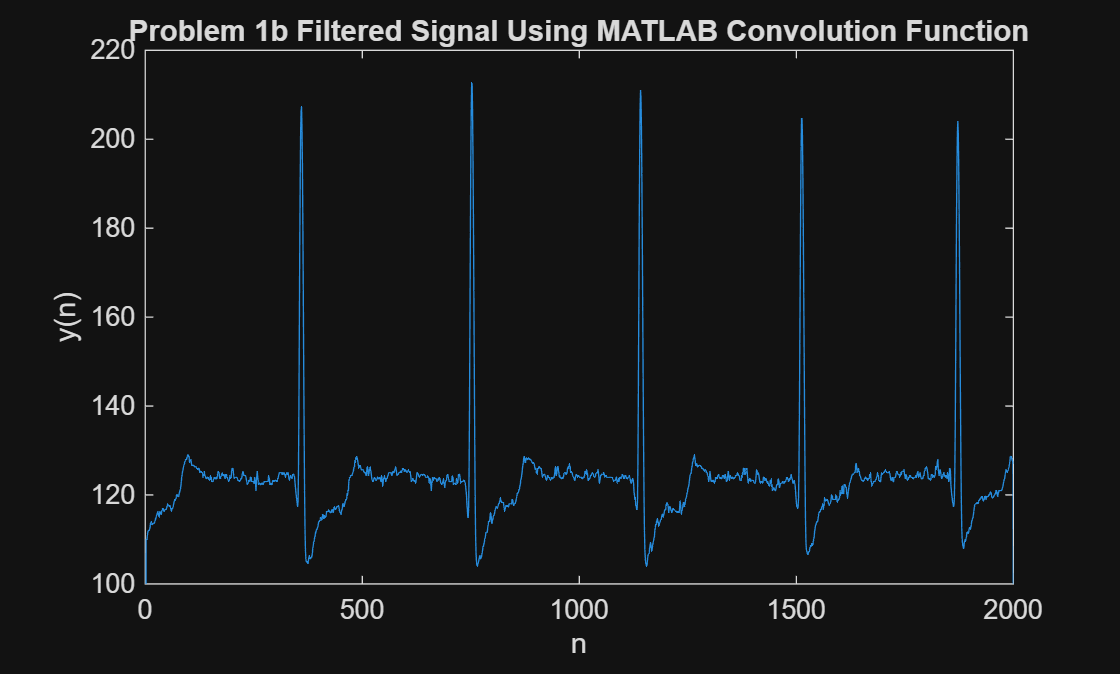

h = [1/3 1/3 1/3];
y = conv(w, h);
n = 0:length(y) - 1;

plot(n, y)
axis([0 2000 100 220]);
title('Problem 1b Filtered Signal Using MATLAB Convolution Function');
xlabel('n');
ylabel('y(n)');

Compared to the unfiltered signal in 1a the filtered signal using MATLAB's convolution command is overall smoother with much fewer high-frequency jumps.

Comapred to the filtered signal using MATLAB's filter command, the filtered signal using MATLAB's convolution command appears the same, though the data could differ slightly in visually imperceptible ways.

Problem 1c

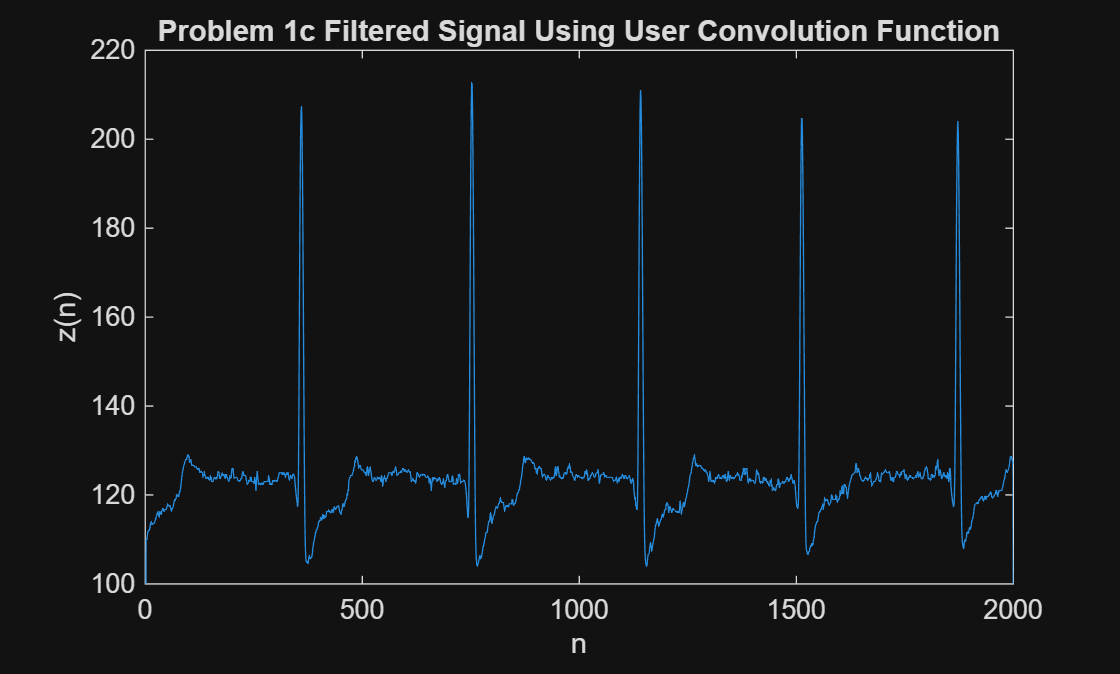

[z, n] = convolution(w, h);
plot(n, z)
axis([0 2000 100 220]);
title('Problem 1c Filtered Signal Using User Convolution Function');
xlabel('n');
ylabel('z(n)');

Problem 2

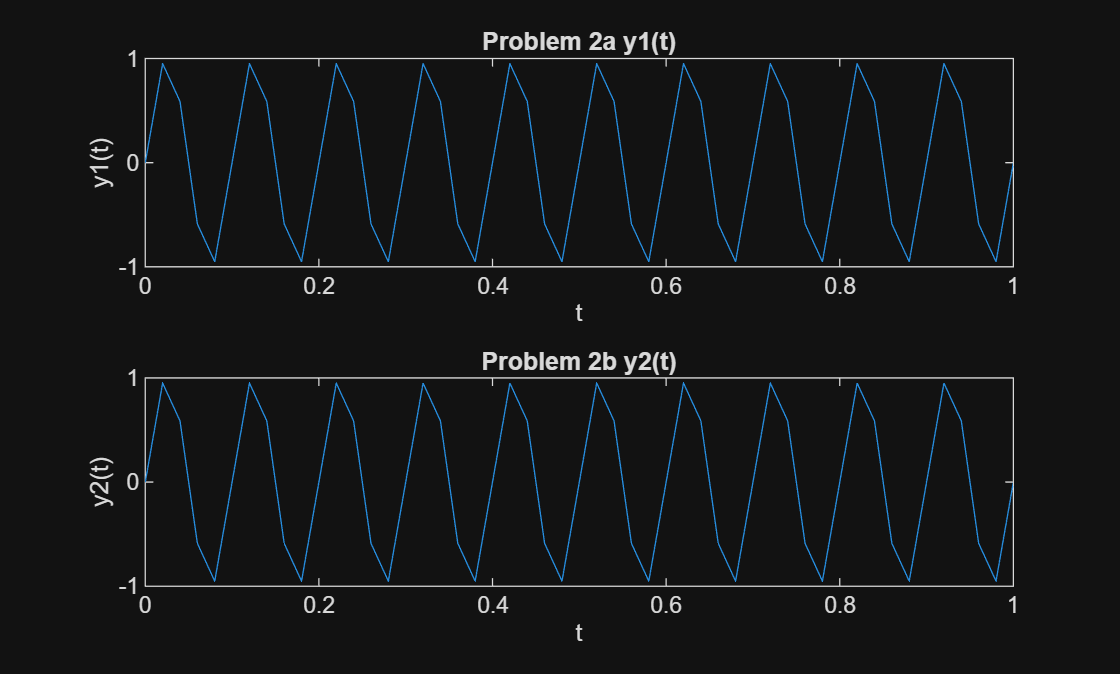

fs = 50; % sample rate in Hz
dt = 1/fs; % sampling interval
t = 0:dt:1; % time varying from 0 to 1
f1 = 10;
f2 = 60;
y1 = sin(2*pi*f1*t);
y2 = sin(2*pi*f2*t);

figure;
subplot(2, 1, 1)
plot(t, y1)
title('Problem 2a y1(t)');
xlabel('t');
ylabel('y1(t)');

subplot(2, 1, 2)
plot(t, y2)
title('Problem 2b y2(t)');
xlabel('t');
ylabel('y2(t)');

Problem 2c

There is no discernable difference between the plots of y1 and y2. This is due to y2 being sampled at 50 Hz, which is lower than y2's Nyquist rate of 120 Hz, causing the signal to be alised and appear like the 10 Hz signal of y1.

Problem 3

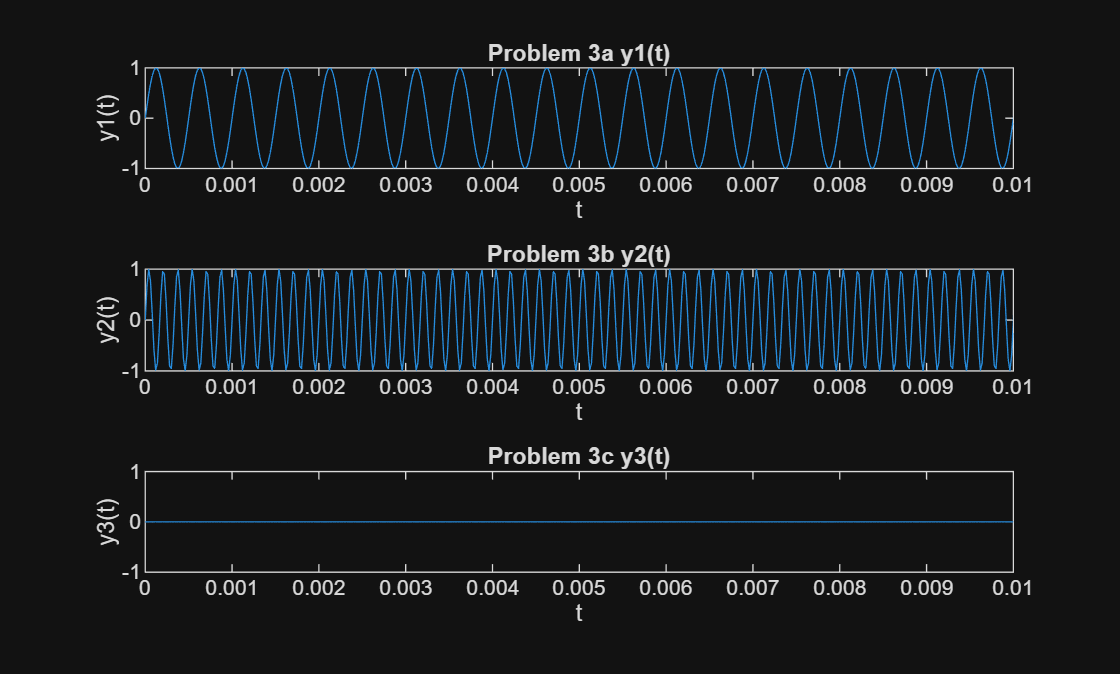

clear;
fs = 50000; % sample rate in Hz
dt = 1/fs; % sampling interval
t = 0:dt:1; % time varying from 0 to 1

y1 = sin(2*pi*2000*t);
y2 = sin(2*pi*6000*t);
y3 = sin(2*pi*25000*t);

figure;
subplot(3, 1, 1)
plot(t, y1)
axis([0 0.01 -1 1])
title('Problem 3a y1(t)');
xlabel('t');
ylabel('y1(t)');

subplot(3, 1, 2)
plot(t, y2)
axis([0 0.01 -1 1])
title('Problem 3b y2(t)');
xlabel('t');
ylabel('y2(t)');

subplot(3, 1, 3)
plot(t, y3)
axis([0 0.01 -1 1])
title('Problem 3c y3(t)');
xlabel('t');
ylabel('y3(t)');

Problem 3 Sounds and Observations

% uncomment one line at a time
%sound(y1, fs)
%sound(y2, fs)
sound(y3, fs)

The waveform y1 produced a somewhat high-pitched continuous tone for roughly half a second.

The waveform y2 produced a higher pitch than y1, though it played for a similar length of time.

The waveform y3 produced a sound outside of human hearing, making it seem as though no sound was played.

Problem 1c Convolution Function

function [c, n] = convolution(f, g)
    N = length(f);
    M = length(g);
    
    L = N + M -1;
    c = zeros(1, L);
    
    for n = 0:L-1
       for k = 0:N-1
           if (n-k >= 0) && (n-k < M)
               c(n+1) = c(n+1) + f(k+1)*g(n-k+1);
           end
       end
    end
    
    n = 0:L-1;
end